## TOPIC 21: Callbacks and simple interfaces

ENGR105, 11/12/20

#### Miscellaneous information: changing the directory and accessing all files in the current folder

- The **current directory** can be retrieved using `cd`. This will save the directory as a character array.

currDir = cd;
disp(currDir)

/Users/raribidesi/Desktop/ENGR 105/Class Notes


- You can use `cd` with a character input to navigate to a **different directory**

cd(currDir)

- `dir` retrieves the list of files in a given directory. If assigned to a variable, it will store the information as a structure array, where each structure corresponds to one file.

dirFiles = dir;

- You can **retrieve a list of file names** from the name field. This can be converted to a cell array using `{}`

files = {dirFiles.name};
size(files)

ans =      1    43


files{5}

ans = 'HW6_test.m'

**Note**: this enables automated processing of a large number of files in a given directory. 

#### Reminder: keyboard callbacks (key press)

In Lecture 20/Topic 19, we produced an example where we can use the `arrow keys` to move a ball across the screen, while `'q'` closes the figure window. The following callback function is located at the end of the LiveScript document.

**Example 1**: Moving ball

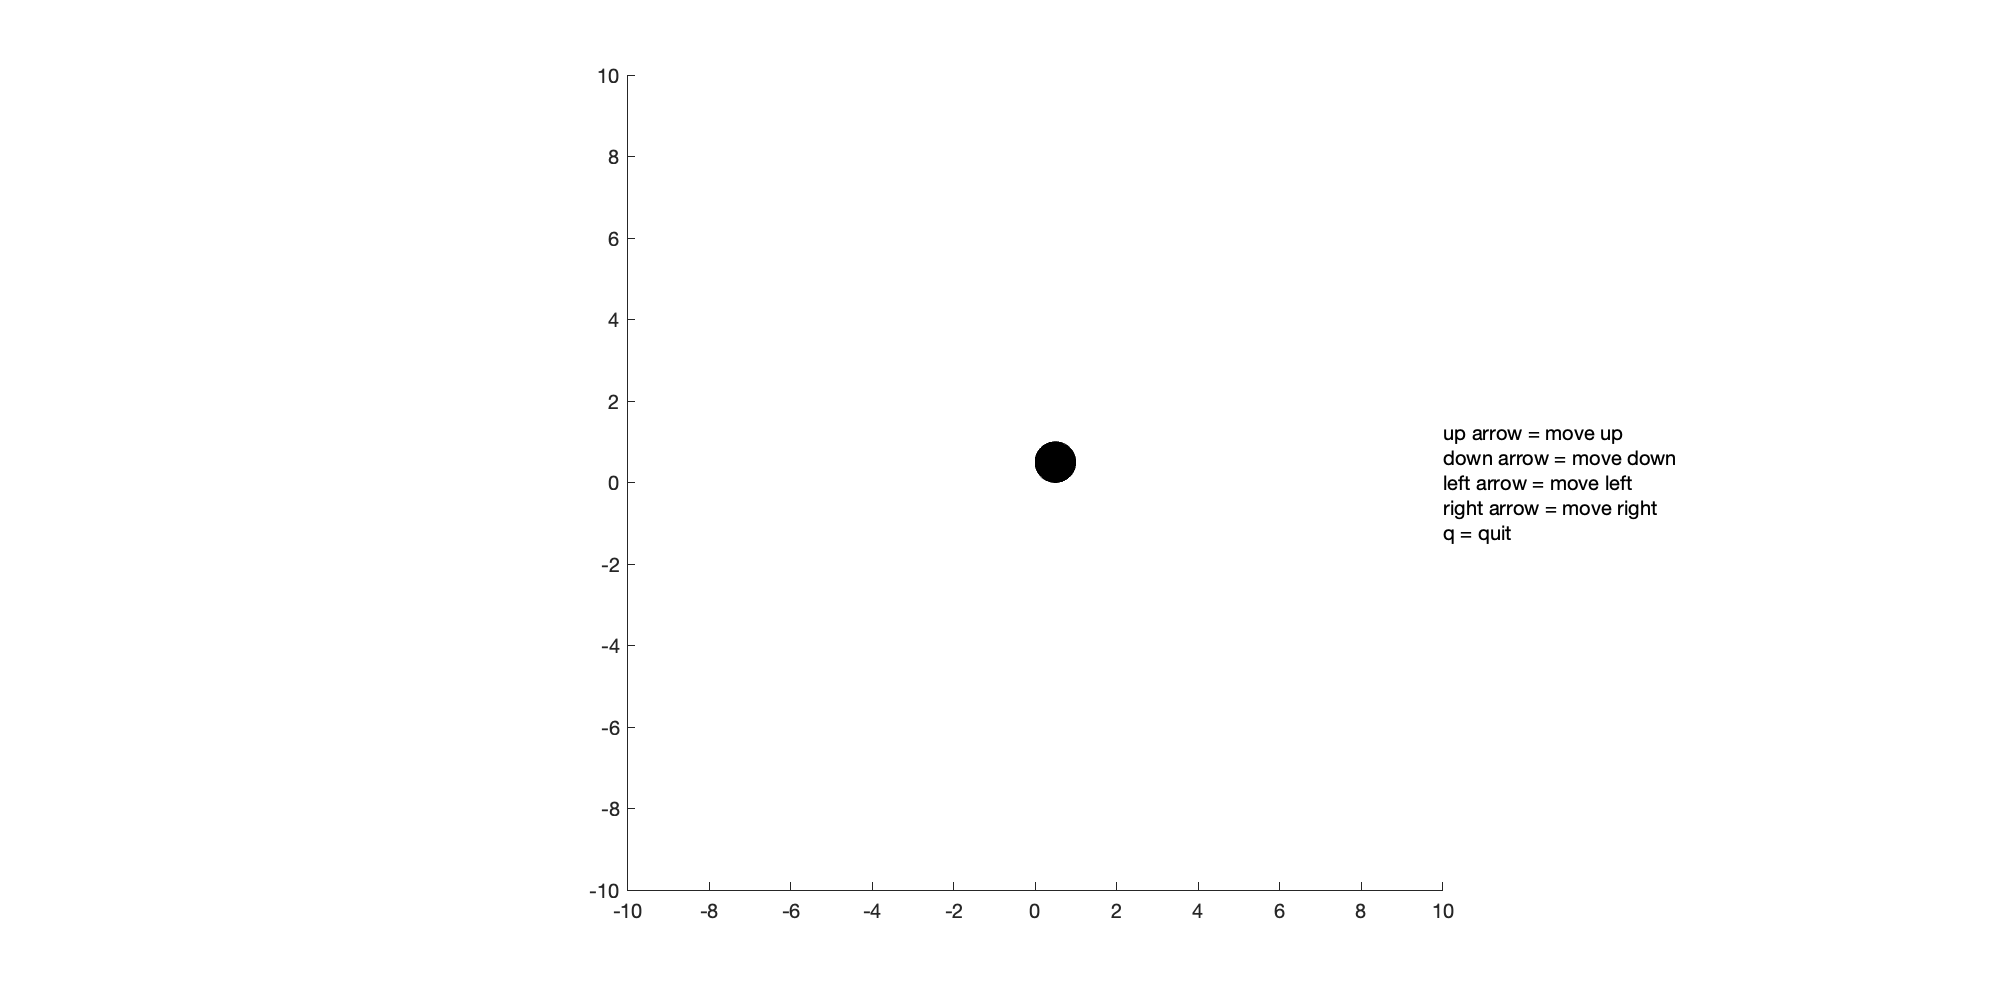

% Initialize the figure and assign the keyboard callback
% function.
hFig = figure('Position',[200,200,1000,500]);

% Specify plot formatting
text(10,0,{'up arrow = move up','down arrow = move down', ...
    'left arrow = move left','right arrow = move right','q = quit'})
axis square
xlim([-10,10])
ylim([-10,10])

% Create a "ball" and place it at [0,0] initially
hBall = rectangle('Position',[0,0,1,1],'Curvature',[1,1]);
hBall.FaceColor = 'k';

% Assign a keyboard call back
hFig.KeyPressFcn = {@DoWhenKeyIsPressed,hBall};

% Set figure to visible -> have it pop out so we can input the keyboard
% call backs
set(hFig,'Visible','on')

**Note**: callback functions do not support outputs.

#### Keyboard callbacks (key release)

In the above example, something happens when we *press a button*. We can have something happen when we release a button. This can be specified using the `'KeyReleaseFcn'` field of the graphics object for the current figure.

**Example 2.** **Produce a game where you must keep moving the ball.** If the player doesn't move for ~ 1 second, display "`Game Over`." Furthermore, make the "ball" become "whiter" as the game approaches the end game scenario.

To create this solution, we must create:

- A function to be assigned to the *key press*

- A function to be assigned to the *key release*

close all % Close previous windows

% Initialize the figure and assign the keyboard callback
% function.
hFig = figure('Position',[200,200,1000,500]);

% Specify plot formatting
text(10,0,{'up arrow = move up','down arrow = move down', ...
    'left arrow = move left','right arrow = move right','q = quit'})
axis square
xlim([-10,10])
ylim([-10,10])

% Create a "ball" and place it at [0,0] initially
hBall = rectangle('Position',[0,0,1,1],'Curvature',[1,1]);
hBall.FaceColor = 'k';  % Default color is black

% Assign a keyboard call back for when a buttom is pressed
hFig.KeyPressFcn = {@ex3_keyPress,hBall};
% Assign a keyboard call back for when a button is release
hFig.KeyReleaseFcn = {@ex3_keyRealease,hBall};

% Set figure to visible -> have it pop out so we can input the keyboard
% call backs
set(hFig,'Visible','on')

**Challenge**. Can you create modifications to the code so that:

- The radius of the ball resets on a key press but increases as the color becomes whiter?

- You want the ball to avoid regions of the playable area?

- At the end ot the game, the game window closes and the new window appears that says "Game Over?" Or the user cannot further move the ball.

**Takeaway note:** *in these cases (and below), callback functions are not compatible with outputs.*

#### Mouse callbacks

Similarly to assigning keyboard callbacks, one can assign callback functions to **mouse operations** as function handles to the appropriate field of a **graphics handle object**. In particular, we will discuss the following fields associated with mouse operations:

- `WindowButtonMotionFcn - `the mouse pointer is moved

- `WindowButtonDownFcn - `the mouse button is pressed

- `WindowButtonUpFcn - `the mouse button is released

**Example 3**. Create a script that tracks the mouse cursor across a figure windows and reports the x and y position at the tip of the cursor.

*Callback function:*

This will utilize a callback associated with the `'WindowButtonMotionFcn'` field, which **executes whenever motion on the figure is detected**.

**Note**: this utilizes `get(``gca``,``'``CurrentPoint``'``)` in the callback function, which reports the location of the mouse button as a `2x3` matrix:

- The 1st row, 1st column of the matrix is the x position of the click

- The 1st row, 2nd column of the matrix is the y position of the click

*Incorporating this into a script:*

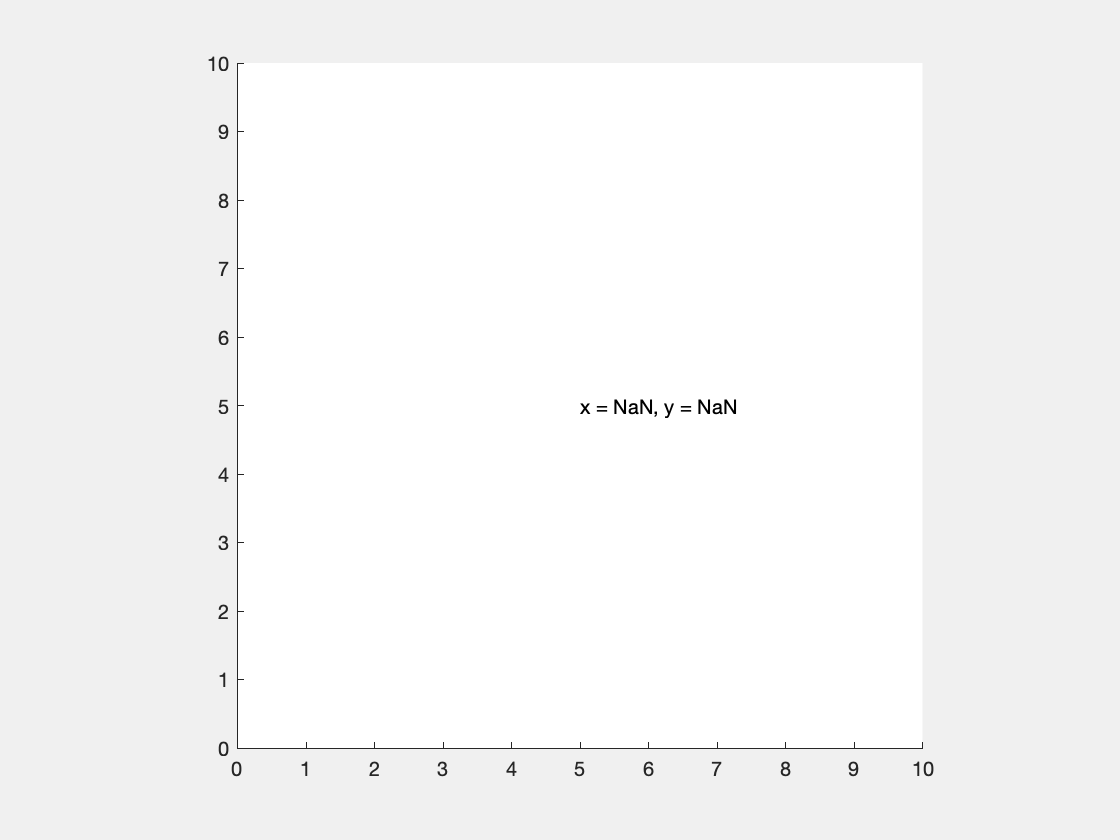

close all % close previous figures

% Create a figure to be associated with the mouse callback
hFig1 = figure('Visible','on');
axis equal
xlim([0,10])
ylim([0,10])

% Initialize a text object for displaying coordinates
g = text(5,5,'x = NaN, y = NaN');


% Assign mouse callback function
hFig1.WindowButtonMotionFcn = {@moveText,g};

**Mouse button clicks** can be registered in a figure window using the `WindowButtonDownFcn` callback. 

**Example 4**. In the following, you can observe the `SelectionType` for different mouse clicks.

close all

% Create a figure and establish the callback associated with a
% mouse button press.
figure('WindowButtonDownFcn',@click,'Visible','on')

- `'normal'` - left mouse button click

- `'alt'` - right mouse button click

- `'extend'` - middle mouse button click

- `'open'` - double click

**Example 5**. Create an **interactive plot **where points can be added to the plot based on the location of the mouse cursor when pressing any mouse button.

*Callback function:*

**Note**: the above  uses `drawnow`. `drawnow` is equivalent to `pause(`*<shortest time based on your computer's processor>*`)` and updates figures and processes any pending callbacks. Use this command if you modify graphics objects and want to see the updates on the screen immediately.

*Incorporating this into a script:*

close all

% Create a figure with mouse button press callback and plot
% NaNs (nothingness) on the figure.
hFig2 = figure('Visible','on');
h = plot(NaN,NaN,'ro-','MarkerFaceColor','r','MarkerSize',5);

% Assign callback function
hFig2.WindowButtonDownFcn = {@plotPoints1,h}

hFig2 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [561 529 560 420]
       Units: 'pixels'

  Show all properties


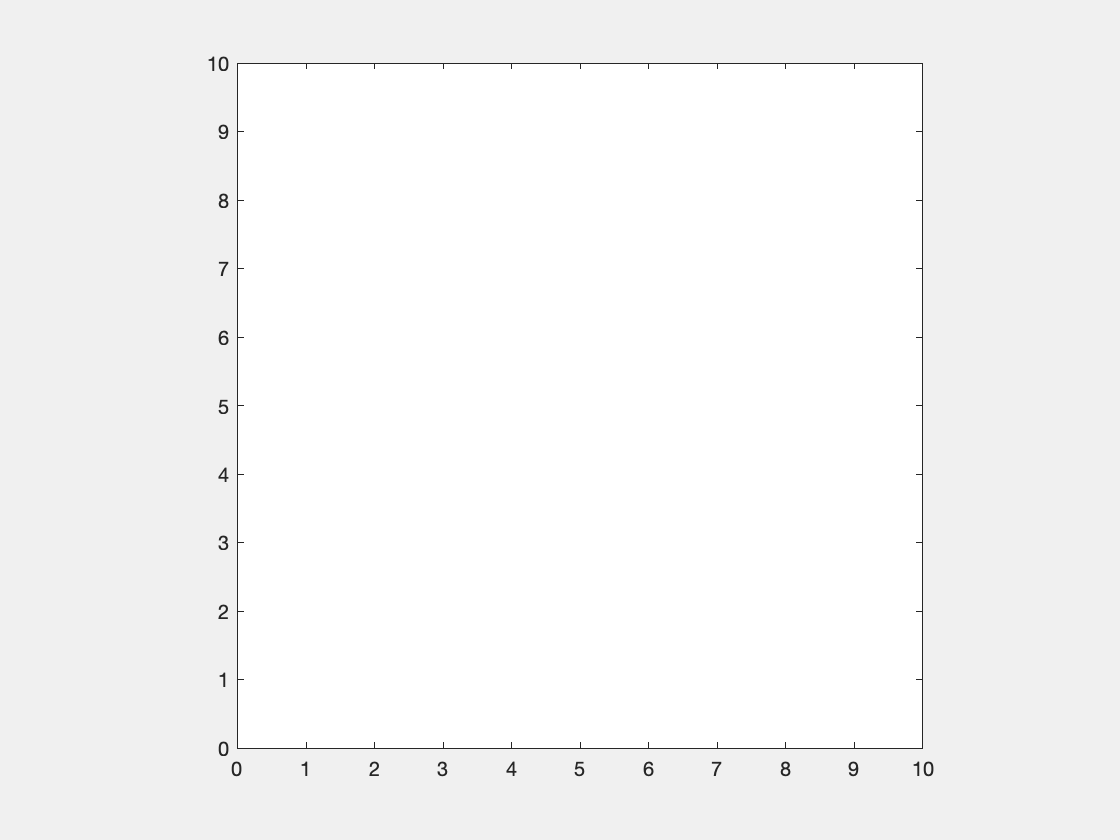


% Graphical parameters
axis equal
xlim([0,10])
ylim([0,10])

**Example 6**. Create an similarly **interactive plot that **populates **lines of different colors** depending on if the left or right mouse button is clicked. 

*Callback function:*

*Incorporating into a script:*

close all % Delete previous

% Create a figure with mouse button press callback
hFig3 = figure('Visible','on');

% Plot each color line, initially as NaN. The first plot (handle = hRed)
% hold the red points and the second plot (handle = hGreen) hold
% the green points.
hRed = plot(NaN,NaN,'ro-','MarkerFaceColor','r','MarkerSize',5);
hold on
hGreen = plot(NaN,NaN,'go-','MarkerFaceColor','g','MarkerSize',5);
hold off

% Assign callback function
hFig3.WindowButtonDownFcn = {@plotPoints2, hRed, hGreen};

axis square
xlim([0,10])
ylim([0,10])

#### Storing data in an interface with `guidata`

In the above example, we **add points** to one of two data sets. What if we want to ***remove points*** in reverse order? This is difficult because callback functions **do not** return outputs. That is, we cannot store the order of the points added.

- To address this issue, `guidata()` can be used to pass variables among callbacks in figures and interfaces. 

- `guidata` is used to update a **structure** variable that is associated with a given figure or interface.

- The following depicts the syntax for `guidata()`. `handles` is a common representation for a data structure that can store information. The name comes from the application of guidata in creating graphical user interfaces using the built-in `guide` designer.

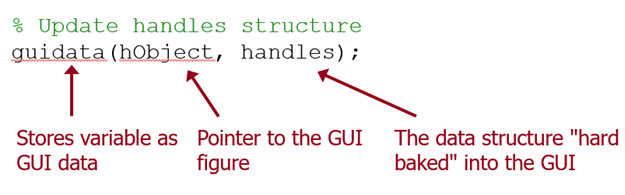

**Note**: guidata is used to both **store** and **retrieve** the data structure.

**Example 7**. For an interactive plot created in Example 6, add a functionality such that 

*Updated callback function:*

*Incorporating into a script:*

close all % Delete previous

% Create a figure with mouse button press callback
hFig3 = figure('Visible','on');

% Create a data structure to store the order of moves
handles.order = cell(0);
% Update the guidata with that data structure
guidata(hFig3,handles);


% Plot each color line, initially as NaN. The first plot (handle = hRed)
% hold the red points and the second plot (handle = hGreen) hold
% the green points.
hRed = plot(NaN,NaN,'ro-','MarkerFaceColor','r','MarkerSize',5);
hold on
hGreen = plot(NaN,NaN,'go-','MarkerFaceColor','g','MarkerSize',5);
hold off

% Assign callback function
hFig3.WindowButtonDownFcn = {@lotPoints3, hRed, hGreen};

axis square
xlim([0,10])
ylim([0,10])

#### Example: Revisiting Tic Tac Toe

In lectures 9 - 11 and in Homework #6, we created an environment for playing Tic Tac Toe.

% Play tic tac toe against AI player who plays randomly
ticTacToe(@playRandom)

     1     0     0
     0     0     0
     0     0     0

     1     0     2
     0     0     0
     0     0     0

     1     0     2
     1     0     0
     0     0     0

     1     0     2
     1     0     0
     0     0     2

     1     0     2
     1     0     0
     1     0     2

1 wins!


**Goal**: we want to create a user interface for playing Tic Tac Toe.

*Our previous methodology:*

- Initialize settings and gameboard

- Sequentially loop through turns as long as a end condition is not satisfied

- If it is the player's turn, input an index number.

- If it is the computer's turn, pick the next position according to some strategy.

- Update gameboard and evaluate end game conditions.

- Iterate as long as necessary

*One possible new methodology:*

- Create a graphics object (a figure)

- On mouse click: the player makes a move, the gameboard is updated, and end game conditions are evaluated

- On mouse release: the computer will make a move, the gameboard is updated, and end game conditions are evaluated

- Once end game conditions are satisfied, the game ends.

**Question**: what variable will need to be "updated" throughout all of this? The gameboard. For this reason, we should anticipate using guidata to store and retrieve the current gameboard.

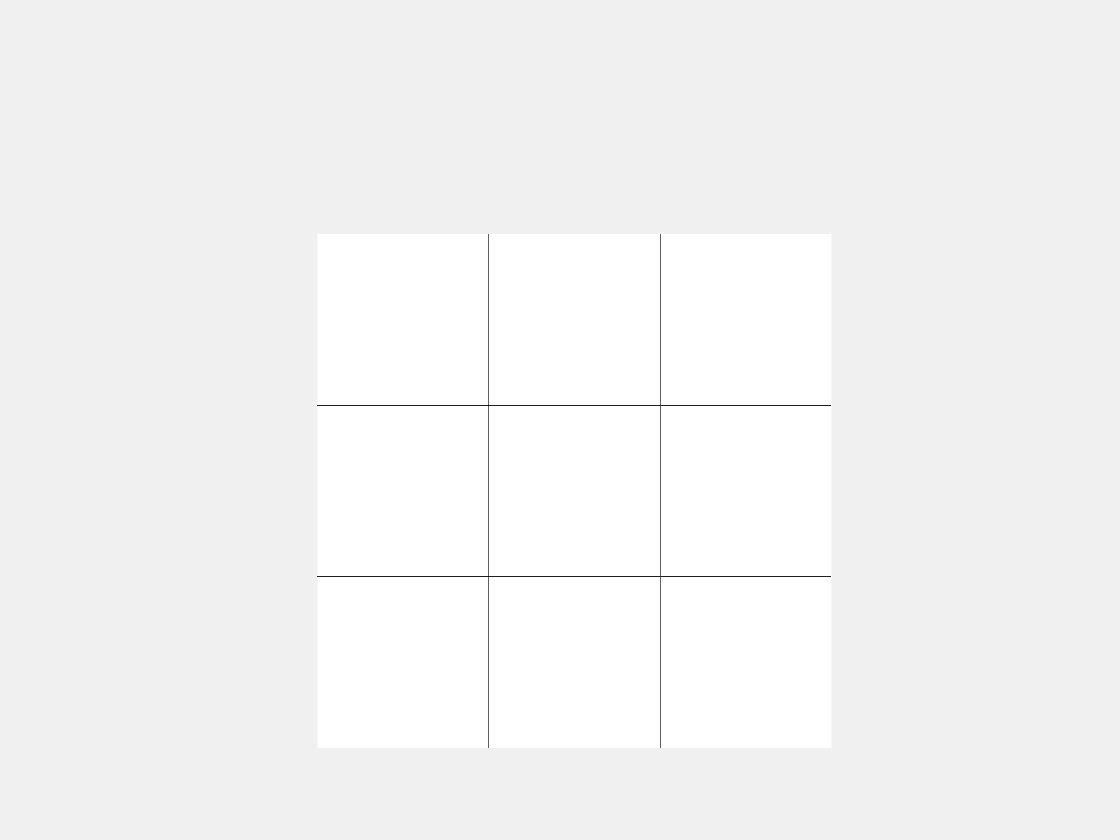

% Create figure objects
h1 = figure('Visible','on');
g1 = axes;

% Plot grid lines
plot([-1,-1],[-4,4],'k-')
hold on
plot([1,1],[-4,4],'k-')
plot([-4,4],[1,1],'k-')
plot([-4,4],[-1,-1],'k-')
hold off

% Modify graphical parameters
xlim([-3,3])
ylim([-3,3])
g1.XColor = 'none';
g1.YColor = 'none';
g1.Position(3:4) = 0.75*g1.Position(3:4);
g1.OuterPosition(1) = 0.125;
axis square

% Create two empty text containers. On every turn, we will update the the
% position of either the next X or next O marker from NaN to the
% appropriate coordinates
x1 = text(NaN(5,1),NaN(5,1),'X','FontName','Arial','FontSize',50,'FontWeight','bold');
x2 = text(NaN(4,1),NaN(4,1),'O','FontName','Arial','FontSize',50,'FontWeight','bold');


% Create data structure to store gameboard
handles.gameboard = zeros(3);
% Store data structure
guidata(h1,handles);

% Assign callback function for mouse click
h1.WindowButtonDownFcn = {@placeX,x1};
% Assign callback function for mouse release
h1.WindowButtonDownFcn = {@place0,x2,@playRandom}

h1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [561 529 560 420]
       Units: 'pixels'

  Show all properties


#### Creating figure UI objects using `uicontrol`

Interactive elements may be added directly to a figure using `uicontrol`. For a list of interactive objects, please see the [MATLAB documentation](https://www.mathworks.com/help/matlab/ref/uicontrol.html). Briefly, the types of objects to be incorporated include:

            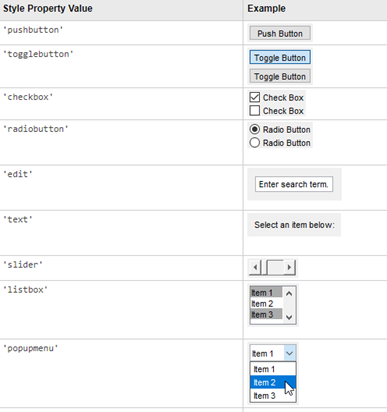

**Example. **Update the Tic Tac Toe code to include a button that resets the game.

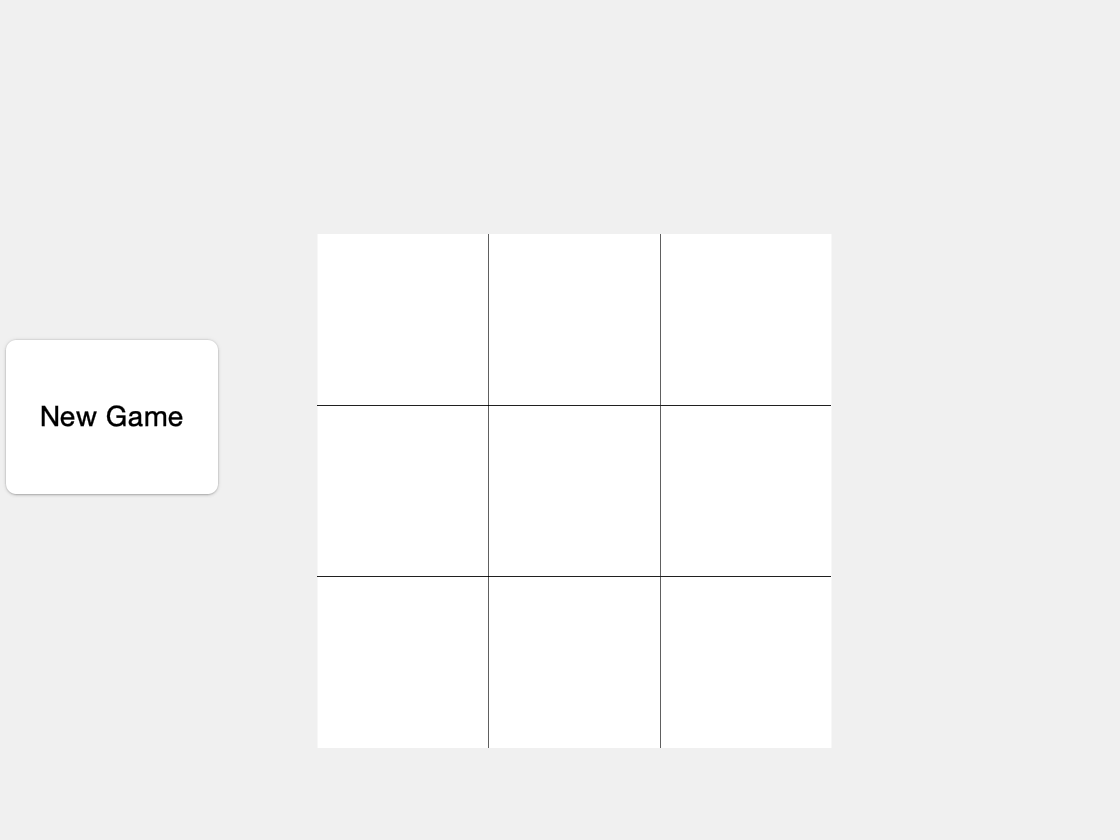

% Create figure objects
h1 = figure('Visible','on');
g1 = axes;

% Plot grid lines
plot([-1,-1],[-4,4],'k-')
hold on
plot([1,1],[-4,4],'k-')
plot([-4,4],[1,1],'k-')
plot([-4,4],[-1,-1],'k-')
hold off

% Modify graphical parameters
xlim([-3,3])
ylim([-3,3])
g1.XColor = 'none';
g1.YColor = 'none';
g1.Position(3:4) = 0.75*g1.Position(3:4);
g1.OuterPosition(1) = 0.125;
axis square

% Create two empty text containers. On every turn, we will update the the
% position of either the next X or next O marker from NaN to the
% appropriate coordinates
x1 = text(NaN(5,1),NaN(5,1),'X','FontName','Arial','FontSize',50,'FontWeight','bold');
x2 = text(NaN(4,1),NaN(4,1),'O','FontName','Arial','FontSize',50,'FontWeight','bold');

% Create data structure to store gameboard
handles.gameboard = zeros(3);
% Store data structure
guidata(h1,handles);

% Assign callback function for mouse click
h1.WindowButtonDownFcn = {@placeX,x1};
% Assign callback function for mouse release
h1.WindowButtonUpFcn = {@placeO,x2,@playRandom};

% Pushbutton to subtract 1 from the current value of the counter
u1 = uicontrol('Style','pushbutton','Units','Normalized','Position',...
    [0,0.4,0.2,0.2],'String','New Game');
u1.Callback = {@resetGame,h1,x1,x2,@placeX,@placeO,@playRandom};
u1.FontSize = 14;

**Functions for this Lecture**

- **Example 1**. Moving ball example (from before)

function DoWhenKeyIsPressed(~,eventdata,hBall)
    % Utilizes keypresses to move the x/y coordinates of the
    % ball or closes the figure.
    
    % Movement increment
    inc = 0.3; 

    % Move up
    if strcmp(eventdata.Key,'uparrow')
        hBall.Position(2) = min(hBall.Position(2)+inc,9);
        
    % Move down
    elseif strcmp(eventdata.Key,'downarrow')
        hBall.Position(2) = max(hBall.Position(2)-inc,-10);
    % Move left
    elseif strcmp(eventdata.Key,'leftarrow') 
        hBall.Position(1) = max(hBall.Position(1)-inc,-10);
    % Move right
    elseif strcmp(eventdata.Key,'rightarrow')   
        hBall.Position(1) = min(hBall.Position(1)+inc,9);
    % Close figure
    elseif strcmp(eventdata.Key,'q')  
        close()
    % Display invalid keystroke
    else
        disp('Key not mapped')
    end
end

- **Example 2**. Key press function

function ex3_keyPress(~,eventdata,hBall)
    % Utilizes keypresses to move the x/y coordinates of the
    % ball or closes the figure.
    
    % Movement increment
    inc = 0.3; 

    % Reset FaceColor to be black
    hBall.FaceColor = 'k';
    
    % Move up
    if strcmp(eventdata.Key,'uparrow')
        hBall.Position(2) = min(hBall.Position(2)+inc,9);
        
    % Move down
    elseif strcmp(eventdata.Key,'downarrow')
        hBall.Position(2) = max(hBall.Position(2)-inc,-10);
    % Move left
    elseif strcmp(eventdata.Key,'leftarrow') 
        hBall.Position(1) = max(hBall.Position(1)-inc,-10);
    % Move right
    elseif strcmp(eventdata.Key,'rightarrow')   
        hBall.Position(1) = min(hBall.Position(1)+inc,9);
    % Close figure
    elseif strcmp(eventdata.Key,'q')  
        close()
    % Display invalid keystroke
    else
        disp('Key not mapped')
    end
end

- **Example 2.** key release function

function ex3_keyRelease(~,~,hBall)
    % Function to be executed when key is released. Takes a graphics object
    % corresponding to the ball as an input

    % Increase the whiteness of the ball until it becomes fully white
    while hBall.FaceColor(1) < 0.9
        
        % Make FaceColor whiter
        hBall.FaceColor = min(hBall.FaceColor + 0.1,1);
    
        % Pause for 100 ms
        pause(0.1)
    end
    
    % If ~1 second passes without moving, game over
    t1 = text(-10,0,'GAME OVER');
    t1.FontSize = 50;
    t1.Color = 'r';
    
end

- **Example 3**. Mouse callback - Depict position of mouse on screen

function moveText(~,~,g)
    % The mouse button motion callback.
    
    % Get the current mouse location.
    pos = get(gca, 'CurrentPoint');
    x = pos(1,1); y = pos(1,2);
    
    % Update the text object readout to the current location
    % and place its location at the cursor tip.
    g.String = ['x = ',num2str(x),', y = ',num2str(y)];
    g.Position = [x, y, 0]; % position 0 in 3rd dimension
end

- **Example 4**. Mouse callback - display selection type, depending on mouse click

function click(h,~)
    % The callback for a mouse button press. Print the mouse
    % button identifier to the command window.
    h.SelectionType
end
 

- **Example 5**. Mouse callback - select points and plot on a graph

function plotPoints1(~,~,h)
    % Call back function for updating a plot
    
    % Get the current mouse location 
    pos = get(gca,'CurrentPoint');
   
    % Update the plot with the new position
    h.XData(end+1) = pos(1,1);
    h.YData(end+1) = pos(1,2);
    drawnow
end

- **Example 6**. Mouse callback - select points and plot depending on right click or left click

function plotPoints2(h,~,hRed,hGreen)
    % Callback function for updating a plot with multiple colored points
    
    % Get the current mouse location.
    pos = get(gca, 'CurrentPoint');
    
    % If a left click: add to the red plot
    if strcmp(h.SelectionType,'normal')
        
        % Add to the data in the red plot
        hRed.XData(end+1) = pos(1,1); 
        hRed.YData(end+1) = pos(1,2);
        drawnow

    % If a right click: add to the green plot
    elseif strcmp(h.SelectionType,'alt')
        
        % Add to the data in the red plot
        hGreen.XData(end+1) = pos(1,1); 
        hGreen.YData(end+1) = pos(1,2);
        drawnow
        
    end
end

**Example 7**. Mouse callback - removing last point

function plotPoints3(h,~,hRed,hGreen)
    % Callback function for updating a plot with multiple colored points
    
    % Get the current mouse location.
    pos = get(gca, 'CurrentPoint');
    
    % Load GUI information
    handles = guidata(h);

    % If a left click: add to the red plot
    if strcmp(h.SelectionType,'normal')
        
        % Add to the data in the red plot
        hRed.XData(end+1) = pos(1,1); 
        hRed.YData(end+1) = pos(1,2);
        drawnow
        
        % Specify that the most recent point was red
        handles.order{end+1} = 'r';

    % If a right click: add to the green plot
    elseif strcmp(h.SelectionType,'alt')
        
        % Add to the data in the red plot
        hGreen.XData(end+1) = pos(1,1); 
        hGreen.YData(end+1) = pos(1,2);
        drawnow
        
        % Specify that the most recent point was red
        handles.order{end+1} = 'g';
        
    % If a middle click (and note empty: delete the most recent point
    elseif strcmp(h.SelectionType,'extend') && ~isempty(handles.order)
        
        % If last point was red
        if strcmp(handles.order{end},'r')
            % Remove last data poitn
            hRed.XData(end) = []; 
            hRed.YData(end) = [];
            drawnow
            
            % Delete last entry
            handles.order(end) = [];
            
        % If last point was green
        else
            % Remove last data poitn
            hGreen.XData(end) = []; 
            hGreen.YData(end) = [];
            drawnow
            
            % Delete last entry
            handles.order(end) = [];

        end
    end
    
    % Update the guidata with the data structure
    guidata(h,handles);
end

- **Tic Tac Toe code from HW 6**

function ticTacToe(compStrategy)
    % Define initial variables and arrays
    gameboard = zeros(3,3); % gameboard that we will populate
    
    % Repeat: alternate for players
    player = 1; % player one
    
    % Logical variable to determine if game should stil be playing
    gameStillGoing = 1;
    
    % Iterate until someone has won (or the game is a draw)
    while gameStillGoing
    
        % Player 1: human player. If it is player 1's turn, specify a
        % position to be played
        if player == 1
        
            % Logical variable corresponding if the move is valid
            invalidMove = 1;
            
            % Make player pick a valid position
            while invalidMove
            
                % Position to play, in single index notation
                playPos = input('Select a position to play...');
        
                if ~isempty(playPos)
                    % Determine if move is allowable
                    invalidMove = all((gameboard(:) == 0)'.*(1:9) ~= playPos);
                end
            end
        
        % Player 2: computer player. If it is player 2's turn, determine the
        % position played based on the algorithm contained within compStrategy().
        else
            % Call a function that will output a position based upon the
            % strategy defined for the computer
            playPos = compStrategy(gameboard);
        end
        
        % Update the gameboard
        gameboard(playPos) = player;
        
        % Step 3: display game board
        disp(gameboard)
        
        % Step 4: evaluate stopping condition -> did someone win?
        gameStillGoing = checkEndGame2(gameboard, player);
        
        % Step 5: change player
        player = mod(player,2)+1;
    end
end

function out = checkEndGame2(gameboard,pl)
    % The purpose of this function is to determine if anyone has won the
    % game or if a draw has occured.
    % Input 1, gameboard: matrix containing moves
    % Input 2, which player's turn is it
    
    % Default condition: game needs to keep going
    out = 1;
    
    % Each row represents a different way in which the player could win
    testMatrix = [gameboard;gameboard';diag(gameboard)';diag(rot90(gameboard))'];
    
    if any(all(testMatrix==pl,2))
        disp(strcat(num2str(pl),' wins!'))
        out = 0;
    elseif sum(gameboard(:)>0) == 9
        disp('Draw!')
        out = 0;
    end
end

function posPlayed = playRandom(gameboard)
    % This function contains code describing the computer player's strategy
    % Note: Students should optimize this and ensure it is well commented

    % Determine available positions to play
    availablePos = (gameboard(:) == 0)'.*(1:9);
    positions = availablePos(availablePos > 0);
    
    % Return a random (available) position. This code thus has the computer
    % play randomly based upon the available positions
    posPlayed = positions(randi(length(positions)));
end

- **Tic Tac Toe user interface**

function placeX(h1,~,x1)
    % The purpose of this function is assign an X once a player has clicked
    % an appropriate location

    % Retrieve current X and Y coordinates
    pos = get(gca,'CurrentPoint');
    pos = pos(1,1:2);
    
    % Convert the mouse click location into one of 9 possible game play
    % positions. NOTE: this is based on the visual gameboard created in the
    % above script
    
    % If click corresponds to index position 3
    if pos(1)<-1 && pos(2)<-1
        playPos = 3;
        % Update position vector. This is what will be assigned to the
        % text that will be added to the figure panel
        pos = [-2.5,-2];
           
    % If click corresponds to index position 2
    elseif pos(1)<-1 && pos(2)<1
        playPos = 2;
        pos = [-2.5,0];
            
    % If click corresponds to index position 1 
    elseif pos(1)<-1
        playPos = 1;
        pos = [-2.5,2];
        
    % If click corresponds to index position 6 
    elseif pos(1)<1 && pos(2)<-1
        playPos = 6;
        pos = [-0.5,-2];
        
    % If click corresponds to index position 5   
    elseif pos(1)<1 && pos(2)<1
        playPos = 5;
        pos = [-0.5,0];
            
    % If click corresponds to index position 4    
    elseif pos(1)<1 
        playPos = 4;
        pos = [-0.5,2];
        
    % If click corresponds to index position 9 
    elseif pos(2)<-1
        playPos = 9;
        pos = [1.5,-2]; 
        
    % If click corresponds to index position 8 
    elseif pos(2)<1
        playPos = 8;
        pos = [1.5,0];
       
    % If click corresponds to index position 7
    else
        playPos = 7;
        pos = [1.5,2];

    end
    

    % Load gameboard information
    handles = guidata(h1);
    
    % Update internal gameboard. Note: the click corresponds to player 1
    handles.gameboard(playPos) = 1;
    
    % Evaluate stopping condition -> did someone win?
    % NOTE: no output is necessary
    checkEndGame3(handles.gameboard,1,h1);
    
    % Create a matrix containing positional information for all text that
    % has been played
    textPos = reshape([x1.Position],3,5)';
    
    % Use the above matrix to determine the turn number from the non NaN values
    numTurn = 6-sum(isnan(textPos(:,1)));
    
    % Update the plot with the new position
    x1(numTurn).Position(1:2) = pos;
    
    % Save data
    guidata(h1,handles);

end


function placeO(h1,~,x2,compStrategy)
    % The purpose of this function is assign an O once a player has clicked
    % an appropriate location

    % Load gameboard information
    handles = guidata(h1);

    % Determine position to play based on input strategy
    playPos = compStrategy(handles.gameboard);

    % Update internal gameboard
    handles.gameboard(playPos) = 2;
    
    % Determine where to place text
    % Note: this is determined entirely by figure that was created
    if playPos == 1
        pos = [-2.5,2];
    elseif playPos == 2
        pos = [-2.5,0];
    elseif playPos == 3
        pos = [-2.5,-2];
    elseif playPos == 4
        pos = [-0.5,2];
    elseif playPos == 5
        pos = [-0.5,0];
    elseif playPos == 6 
        pos = [-0.5,-2];
    elseif playPos == 7 
        pos = [1.5,2];
    elseif playPos == 8 
        pos = [1.5,0];
    else
        pos = [1.5,-2]; 
    end
    
    % Create a matrix containing positional information for all text that
    % has been played
    textPos = reshape([x2.Position],3,4)';
    
    % Use the above matrix to determine the turn number from the non NaN values
    numTurn = 5-sum(isnan(textPos(:,1)));
    
    % Update the plot with the new position
    x2(numTurn).Position(1:2) = pos;

    % Step 4: evaluate stopping condition -> did someone win?
    checkEndGame3(handles.gameboard,2,h1);
    
    % Save data
    guidata(h1,handles);
end

function checkEndGame3(gameboard,pl,h1)
    % The purpose of this function is to determine if anyone has won the
    % game or if a draw has occured.
    % Input 1, gameboard: matrix containing moves
    % Input 2, which player's turn is it
    % Input 3, graphics object handle corresponding to figure window

    % Each row represents a different way in which the player could win
    testMatrix = [gameboard;gameboard';diag(gameboard)';diag(rot90(gameboard))'];
    
    % If any three in a rows have happened
    if any(all(testMatrix==pl,2))
        % Remove click press and release function handles
        h1.WindowButtonDownFcn = '';
        h1.WindowButtonUpFcn = '';
        % Add text saying that the player won
        x3 = text(-5,5,['Player ',num2str(pl),' wins!']);
        x3.FontSize = 50;
        x3.Color = 'r';
        

    % If nine turns have occured, then the game is a draw
    elseif sum(gameboard(:)>0) == 9
        % Remove click press and release function handles
        h1.WindowButtonDownFcn = '';
        h1.WindowButtonUpFcn = '';
        % Add text saying that the player won
        x3 = text(-2,5,['Draw!']);
        x3.FontSize = 50;
        x3.Color = 'r';
    end
end

- User interface control object to reset game

function resetGame(~,~,h,x1,x2,f1,f2,f3)
    % To be assign to some pushbutton for resetting the game

    % Create data structure to store gameboard
    handles.gameboard = zeros(3);
    % Store data structure
    guidata(h,handles);

    % Create two empty text containers. On every turn, we will update the the
    % position of either the next X or next O marker from NaN to the
    % appropriate coordinates
    for k = 1:4
        x1(k).Position(1:2) = nan(1,2);
        x2(k).Position(1:2) = nan(1,2);
    end
    x1(5).Position(1:2) = nan(1,2);

    % Assign callback function for mouse click
    h.WindowButtonDownFcn = {f1,x1};
    % Assign callback function for mouse release
    h.WindowButtonUpFcn = {f2,x2,f3};


end